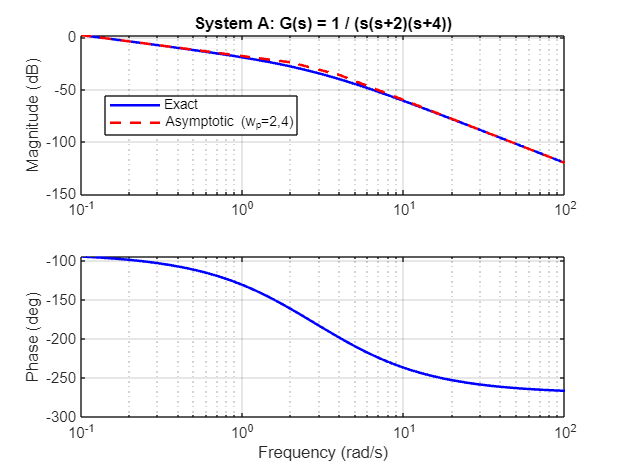

% EE352 Automatic Control
% Asymptotic and Exact Bode Diagrams for 4 Systems
% Question 2
% a) G(s) = 1 / (s(s+2)(s+4))
% b) G(s) = 1 / ((s+1)(s+2-j)(s+2+j))
% c) G(s) = (s+2) / ((s+1)(s+3-j)(s+3+j))
% d) G(s) = 1 / (s(s+1)(s+3)(s+4))

clc;
clear;
close all;

s = tf('s');

%% System A: G(s) = 1 / (s(s+2)(s+4))
% Standard form: G(s) = (1/8) / (s * (0.5s+1) * (0.25s+1))
% Break Frequencies: w_p1 = 2 rad/s, w_p2 = 4 rad/s. Plus origin pole (w=0).
% Low frequency asymptote slope: -20 dB/dec crossing 1 rad/s at 20*log10(1/8) = -18.06 dB
Ga = 1 / (s * (s + 2) * (s + 4));

wa_asymp = [0.1, 2, 4, 100];
ma_asymp = zeros(size(wa_asymp));
ma_asymp(1) = 20*log10(1/8) - 20*log10(wa_asymp(1)); % Starts with -20 dB/dec slope due to 1/s
ma_asymp(2) = 20*log10(1/8) - 20*log10(wa_asymp(2)); % Pole at w=2
ma_asymp(3) = ma_asymp(2) - 40*log10(wa_asymp(3)/wa_asymp(2)); % Slope becomes -40 dB/dec
ma_asymp(4) = ma_asymp(3) - 60*log10(wa_asymp(4)/wa_asymp(3)); % Slope becomes -60 dB/dec

figure('Name', 'System A: Asymptotic vs Exact Bode');
[m, p, w] = bode(Ga, {0.1, 100});
subplot(2,1,1);
semilogx(w, 20*log10(squeeze(m)), 'b', 'LineWidth', 1.5); hold on;
semilogx(wa_asymp, ma_asymp, 'r--', 'LineWidth', 1.5);
grid on; title('System A: G(s) = 1 / (s(s+2)(s+4))'); ylabel('Magnitude (dB)');
legend('Exact', 'Asymptotic (w_p=2,4)', 'Location', 'Best');
subplot(2,1,2);
semilogx(w, squeeze(p), 'b', 'LineWidth', 1.5); grid on;
ylabel('Phase (deg)'); xlabel('Frequency (rad/s)');

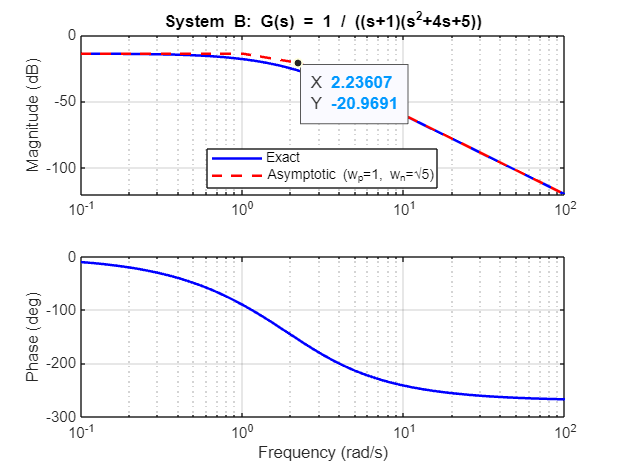


%% System B: G(s) = 1 / ((s+1)(s+2-j)(s+2+j))
% Expand quadratic: (s+2-j)(s+2+j) = (s+2)^2 + 1 = s^2 + 4s + 5
% G(s) = 1 / ((s+1)(s^2 + 4s + 5))
% Standard form: G(s) = (1/5) / ((s+1) * (1/5*s^2 + 4/5*s + 1))
% Break Frequencies: w_p1 = 1 rad/s.
% Complex pair: w_n = sqrt(5) ≈ 2.236 rad/s.
Gb = 1 / ((s + 1) * (s^2 + 4*s + 5));

wb_asymp = [0.1, 1, sqrt(5), 100];
mb_asymp = zeros(size(wb_asymp));
mb_asymp(1) = 20*log10(1/5); % DC Gain: 1/5
mb_asymp(2) = 20*log10(1/5); % Flat until w=1
mb_asymp(3) = mb_asymp(2) - 20*log10(wb_asymp(3)/wb_asymp(2)); % Slope -20 dB/dec
mb_asymp(4) = mb_asymp(3) - 60*log10(wb_asymp(4)/wb_asymp(3)); % Slope -60 dB/dec

figure('Name', 'System B: Asymptotic vs Exact Bode');
[m, p, w] = bode(Gb, {0.1, 100});
subplot(2,1,1);
semilogx(w, 20*log10(squeeze(m)), 'b', 'LineWidth', 1.5); hold on;
semilogx(wb_asymp, mb_asymp, 'r--', 'LineWidth', 1.5);
grid on; title('System B: G(s) = 1 / ((s+1)(s^2+4s+5))'); ylabel('Magnitude (dB)');
legend('Exact', 'Asymptotic (w_p=1, w_n=\surd5)', 'Location', 'Best');
subplot(2,1,2);
semilogx(w, squeeze(p), 'b', 'LineWidth', 1.5); grid on;
ylabel('Phase (deg)'); xlabel('Frequency (rad/s)');

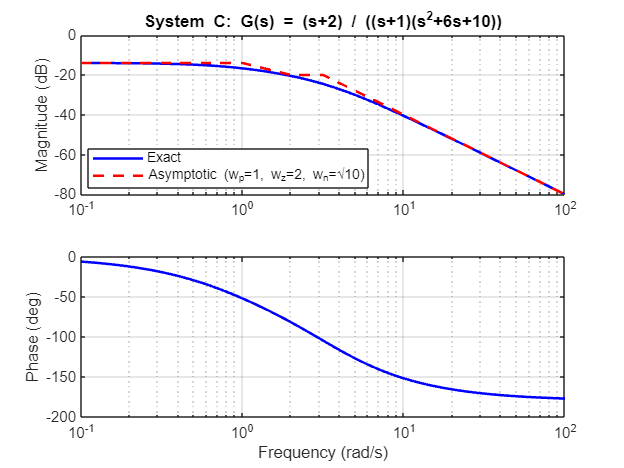


%% System C: G(s) = (s+2) / ((s+1)(s+3-j)(s+3+j))
% Expand quadratic: (s+3-j)(s+3+j) = (s+3)^2 + 1 = s^2 + 6s + 10
% G(s) = (s+2) / ((s+1)(s^2 + 6s + 10))
% Standard Form: G(s) = [2*(0.5s+1)] / [10*(s+1)*(0.1s^2 + 0.6s + 1)] = 0.2*(0.5s+1) / (...)
% Break Frequencies: w_z1 = 2 rad/s. w_p1 = 1 rad/s. w_n = sqrt(10) ≈ 3.16 rad/s.
Gc = (s + 2) / ((s + 1) * (s^2 + 6*s + 10));

wc_asymp = [0.1, 1, 2, sqrt(10), 100];
mc_asymp = zeros(size(wc_asymp));
mc_asymp(1) = 20*log10(2/10); % DC Gain
mc_asymp(2) = mc_asymp(1); % Flat until w=1 (pole)
mc_asymp(3) = mc_asymp(2) - 20*log10(wc_asymp(3)/wc_asymp(2)); % Slope -20 dB/dec until w=2 (zero)
mc_asymp(4) = mc_asymp(3); % Slope -20+20=0 dB/dec until w=sqrt(10) (complex pole pair)
mc_asymp(5) = mc_asymp(4) - 40*log10(wc_asymp(5)/wc_asymp(4)); % Slope -40 dB/dec

figure('Name', 'System C: Asymptotic vs Exact Bode');
[m, p, w] = bode(Gc, {0.1, 100});
subplot(2,1,1);
semilogx(w, 20*log10(squeeze(m)), 'b', 'LineWidth', 1.5); hold on;
semilogx(wc_asymp, mc_asymp, 'r--', 'LineWidth', 1.5);
grid on; title('System C: G(s) = (s+2) / ((s+1)(s^2+6s+10))'); ylabel('Magnitude (dB)');
legend('Exact', 'Asymptotic (w_p=1, w_z=2, w_n=\surd10)', 'Location', 'Best');
subplot(2,1,2);
semilogx(w, squeeze(p), 'b', 'LineWidth', 1.5); grid on;
ylabel('Phase (deg)'); xlabel('Frequency (rad/s)');

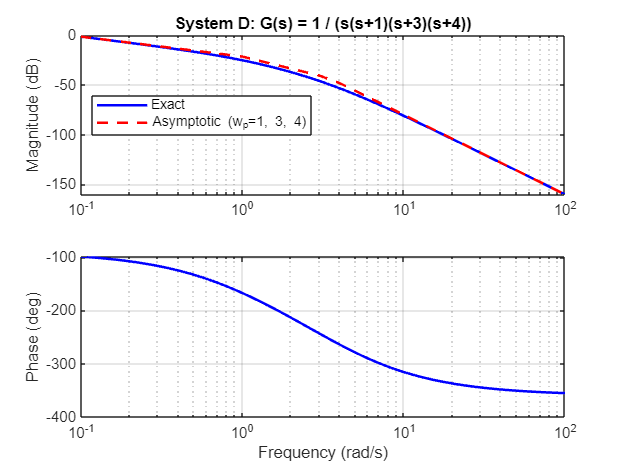


%% System D: G(s) = 1 / (s(s+1)(s+3)(s+4))
% Standard Form: G(s) = (1/12) / (s*(s+1)*(s/3+1)*(s/4+1))
% Break Frequencies: w_p1=1, w_p2=3, w_p3=4 rad/s. Origin pole (w=0).
% Low freq asymptote: -20 dB/dec, crossing w=1 at 20*log10(1/12) = -21.58 dB.
Gd = 1 / (s * (s + 1) * (s + 3) * (s + 4));

wd_asymp = [0.1, 1, 3, 4, 100];
md_asymp = zeros(size(wd_asymp));
md_asymp(1) = 20*log10(1/12) - 20*log10(wd_asymp(1)); % Start -20 dB/dec
md_asymp(2) = 20*log10(1/12) - 20*log10(wd_asymp(2)); % Hits pole w=1
md_asymp(3) = md_asymp(2) - 40*log10(wd_asymp(3)/wd_asymp(2)); % Slope -40 dB/dec until w=3
md_asymp(4) = md_asymp(3) - 60*log10(wd_asymp(4)/wd_asymp(3)); % Slope -60 dB/dec until w=4
md_asymp(5) = md_asymp(4) - 80*log10(wd_asymp(5)/wd_asymp(4)); % Slope -80 dB/dec

figure('Name', 'System D: Asymptotic vs Exact Bode');
[m, p, w] = bode(Gd, {0.1, 100});
subplot(2,1,1);
semilogx(w, 20*log10(squeeze(m)), 'b', 'LineWidth', 1.5); hold on;
semilogx(wd_asymp, md_asymp, 'r--', 'LineWidth', 1.5);
grid on; title('System D: G(s) = 1 / (s(s+1)(s+3)(s+4))'); ylabel('Magnitude (dB)');
legend('Exact', 'Asymptotic (w_p=1, 3, 4)', 'Location', 'Best');
subplot(2,1,2);
semilogx(w, squeeze(p), 'b', 'LineWidth', 1.5); grid on;
ylabel('Phase (deg)'); xlabel('Frequency (rad/s)');